# Time-Sync & Crop Videos, and extract frames from the videos!

*Author: Kamryn Norton*

## *Sync and Crop*

Time-sync and crop videos based on identifiable features and frame numbers as follows:

- Use VideoViewer (MATLAB app) to identify a visual feature (ie light turning on/off). 

- Note/record the frame at which this feature is visible (and it needs to be **unique**, and observed by ***all*** cameras). 

- Repeat the process for all (4) cameras. 

- Calculate the difference in frames between the first occuring camera and the rest (see code, lines 1-7). These differences will be used to calculate the start frames for each camera: ie if camera 1 has a difference of 0, it is the first camera/origin, and if you want your cropped video to start at frame 400 of camera 1, the other cameras will start at 400+difference. 

- Decide on the number of frames needed for the cropped video (ie if you want a 10 second video, note the frame rate is 240fps so you need 10*240 frames). Alter the variable called '*totalNumFrames*' to store this.

- Alter the input and output paths of each camera. Input should be the file you are cropping, and output should be the path and name you want to save the new video as.

- Alter the start frames with reference to steps 3&4. 

Use the code below to store the frame indices and calculate the frame differences:

featureCam1 = 30305;
featureCam2 = 29783;
featureCam3 = 29412;
featureCam4 = 29139;


featureIndices = [featureCam1 featureCam2 featureCam3 featureCam4];
lowest = min(featureIndices);
featureDiff = array2table([featureIndices; featureIndices - lowest],...                  
    "VariableNames",["Cam1" "Cam2" "Cam3" "Cam4"], "RowNames",["feature Index","Difference from Lowest"])

featureDiff = 2×4 table
                              Cam1     Cam2     Cam3     Cam4 
                              _____    _____    _____    _____

    feature Index             30305    29783    29412    29139
    Difference from Lowest     1166      644      273        0


featureDiff2 = array2table([featureIndices; lowest-featureIndices],...                  
    "VariableNames",["Cam1" "Cam2" "Cam3" "Cam4"], "RowNames",["feature Index","Difference from Lowest"])

featureDiff2 = 2×4 table
                              Cam1     Cam2     Cam3     Cam4 
                              _____    _____    _____    _____

    feature Index             30305    29783    29412    29139
    Difference from Lowest    -1166     -644     -273        0


%00:08-01:52 = (60+52-8)*240
%start = 8*240
totalNumFrames = 22240; %number of frames needed for entire video length = seconds*240.

## Time-Sync Calibration Video

CAM1

input1 = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera1\GX010014.MP4";
output1 = "D:\Beshte completed\Calibration\CAM1_timesynced";
start1 = featureDiff.Cam1(2)+1;
utilities.cutVideo(input1, output1, start1, totalNumFrames);

CAM2

input2 = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera2\GX010011.MP4";
output2 = "D:\Beshte completed\Calibration\CAM2_timesynced";
start2 = featureDiff.Cam2(2)+1; 
utilities.cutVideo(input2, output2, start2, totalNumFrames);

CAM3

input3 = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera3\GX010011.MP4";
output3 = "D:\Beshte completed\Calibration\CAM3_timesynced";
start3 = featureDiff.Cam3(2)+1; 
utilities.cutVideo(input3, output3, start3, totalNumFrames);

CAM4

input4 = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera4\GX010012.MP4";
output4 = "D:\Beshte completed\Calibration\CAM4_timesynced";
start4 = featureDiff.Cam4(2)+1; 
utilities.cutVideo(input4, output4, start4, totalNumFrames);

## Extract Frames from Synced Calibration Videos

% % extractDir = "D:\Calibration";
% % destinationDir = "D:\Calibration";
% % frameInterval = 16; %8 = 30 fps; 4 = 60fps; 16 = 15fps
% % utilities.extractFrames(extractDir, frameInterval, destinationDir)

## Audio Syncing Original GoPro Video to IMU 

Identifying the time delay between gopros and imu. Make sure to use the camera footage that was started LAST (has the lowest feature index) since the delay is shorter, and is what the cropping is based on (ie the video with the smallest feature index is assumed to be real-time, the rest are shifted by a frame count to match real-time, so sync the imu to 'real-time').

cameraAudio = "F:\Cheetah Bakkie 2\09_07_2024\1_Zorro\Camera4\GX010015.MP4";
IMUAudio = "F:\Cheetah Bakkie 2\09_07_2024\1_Zorro\IMU\Zorro_day2-2024-07-09_06-05-33\Microphone.mp4";
startFrame = 1;

if exist('audio1','var')==0 && exist('audio2','var')==0
    [audio1, fs1] = audioread(cameraAudio);
    [audio2, fs2] = audioread(IMUAudio);
    audio1mono = mean(audio1,2); %gopro audio is stereo - convert to mono

end

if fs1~=fs2
    fs = min(fs1, fs2);
    audio1resample = resample(audio1mono, fs, fs1);
    audio2resample = resample(audio2, fs, fs2);
else
    fs = fs1; % or fs2
end

audio1CROP = audio1resample(1:round(length(audio1resample)/4));
audio2CROP = audio2resample(1:round(length(audio2resample)/4));
%When video takes really long time before imu started:
% audio1CROP = audio1resample(round(startFrame/fs):round(length(audio1resample)/2));
% audio2CROP = audio2resample(1:round(length(audio2resample)/2));
figure; 
plot(audio1CROP); hold on;
plot(audio2CROP); hold off;
legend('Camera Audio', 'IMU Audio', location='best')
xlabel('Sample index')
ylabel('Decibels relative to Full Scale (dBFS)')
lim = 1000000

lim = 1000000

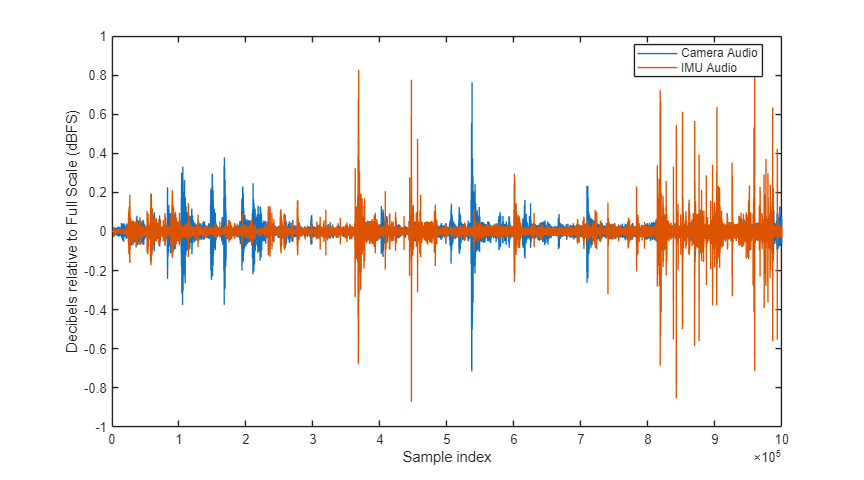

xlim([0 lim])
set(gcf,'Units','inches','Position',[1 1 9 5]);

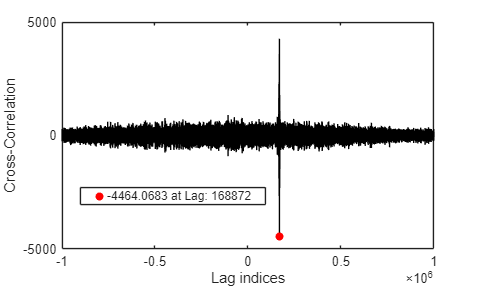

% print(gcf,'-dpng','-r600','soundsignals.png');

[C, LAG_indices] = xcorr(audio1CROP,audio2CROP);
[~, idx] = max(abs(C));
figure;
plot(LAG_indices,C,Color='k'); hold on
scatter(LAG_indices(idx),min(C),"filled", "red")

xlabel('Lag indices')
ylabel('Cross-Correlation')
xlim([-lim, lim])


legend(["",sprintf("%0.4f at Lag: %d",min(C),LAG_indices(idx))], "Position", [0.1662 0.2943 0.3880, 0.0469])
set(gcf,'Units','inches','Position',[1 1 5 3]);
print(gcf,'-dpng','-r600','soundXcorr.png');


idx

idx = 3977811

imu_time_delay = LAG_indices(idx) / fs %seconds

imu_time_delay = 10.5545

imu_frame_delay = 240*imu_time_delay 

imu_frame_delay = 2.5331e+03

savepath = "F:\Cheetah Bakkie 2\09_07_2024\1_Zorro";
save(fullfile(savepath,'sync_metrics'),"imu_time_delay","imu_frame_delay", 'cameraAudio',"IMUAudio")

Now the time/frame delay can be used to synchronise the IMU data to the camera footage.

## Crop A Raw Video to its events and time-sync 

Change event log table (manually import), cheetah name and the paths.

eventLogTable = "F:\Cheetah Bakkie 2\09_07_2024\1_Zorro\eventlogTable.mat" ;
datalog = load(eventLogTable,"datalogS3");
datalog = datalog.datalogS3;
cheetah = "zorro";
savelog = "F:\Cheetah Bakkie 2\09_07_2024\1_Zorro";

Code will automate it all

for i=1:height(datalog)

    %Instantiation
    startframesMatrix=[];
    mins = datalog.m(i);
    secs = datalog.s(i);
    time = mins*60 + secs;
    startframe = time*240; %from the smallest feature index camera (assumed real time).
    vid_duration = datalog.Duration(i); %seconds
    newname = cheetah + num2str(i);

    % Do extraction
        % input = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera1\GX010014.MP4";
        % output = "D:\Beshte completed\Camera1\"+newname;
        % start = startframe+featureDiff.Cam1(2); 
        % startframesMatrix = [startframesMatrix, start];
        % totalNumFrames = vid_duration*240;
        % utilities.cropShortVideo(input, output, start, totalNumFrames);
        % % 
        % input = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera2\GX010011.MP4";
        % output = "D:\Beshte completed\Camera2\"+newname;
        % start = startframe+featureDiff.Cam2(2);
        % startframesMatrix = [startframesMatrix, start];
        % totalNumFrames = vid_duration*240;
        % utilities.cropShortVideo(input, output, start, totalNumFrames);
        % % 
        % input = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera3\GX010011.MP4";
        % output = "D:\Beshte completed\Camera3\"+newname;
        % start = startframe+featureDiff.Cam3(2);
        % startframesMatrix = [startframesMatrix, start];
        %  totalNumFrames = vid_duration*240;
        % utilities.cropShortVideo(input, output, start, totalNumFrames);
        % 
        % input = "D:\Cheetah Bakkie 2\08_07_2024\4_Beshte\Camera4\GX010012.MP4";
        % output = "D:\Beshte completed\Camera4\"+newname;
        % start = startframe+featureDiff.Cam4(2);
        % startframesMatrix = [startframesMatrix, start];
        % totalNumFrames = vid_duration*240;
        % utilities.cropShortVideo(input, output, start, totalNumFrames);

     % Save and display progress
     display("Finished with "+ newname)
     imu_start_frame = startframe-imu_frame_delay;
     imu_start_time_seconds = time-imu_time_delay;
     note = "Zorro IMU data was confused with amelia originally";
     % startframesMatrix = array2table(startframesMatrix,'VariableNames', ["Cam1", "Cam2", "Cam3", "Cam4"]);
     save(fullfile(savelog, newname+"_imuSyncInfo"),"imu_start_time_seconds", "imu_start_frame", 'vid_duration', 'note');
     % save(fullfile(savelog, newname+"_SyncInfo"),"startframesMatrix", 'vid_duration', 'note');

end

    "Finished with zorro1"

    "Finished with zorro2"

    "Finished with zorro3"

    "Finished with zorro4"

    "Finished with zorro5"

    "Finished with zorro6"

    "Finished with zorro7"

    "Finished with zorro8"

    "Finished with zorro9"

    "Finished with zorro10"

    "Finished with zorro11"

    "Finished with zorro12"

    "Finished with zorro13"

    "Finished with zorro14"

    "Finished with zorro15"

    "Finished with zorro16"

    "Finished with zorro17"

    "Finished with zorro18"

    "Finished with zorro19"

    "Finished with zorro20"

    "Finished with zorro21"

    "Finished with zorro22"

    "Finished with zorro23"

    "Finished with zorro24"

